HP Z24X in WO62/3133 measured with CL-500A and Excel on 6/5/2022

spec_z24x = csvread('hpz24x_rgb.csv');

ls = LightSim

ls =   LightSim with properties:

            col_spec: [1024×401 double]
             spd_max: [401×1 double]
             spd_min: [401×1 double]
        spd_max_date: 03-Jun-2022 14:25:19
        spd_min_date: 03-Jun-2022 14:24:34
           classpath: 'C:\Users\wayne\Documents\GitHub\MIS_acquire\@LightSim'
    colorchecker_rgb: [24×3 double]


sc = 0.0700

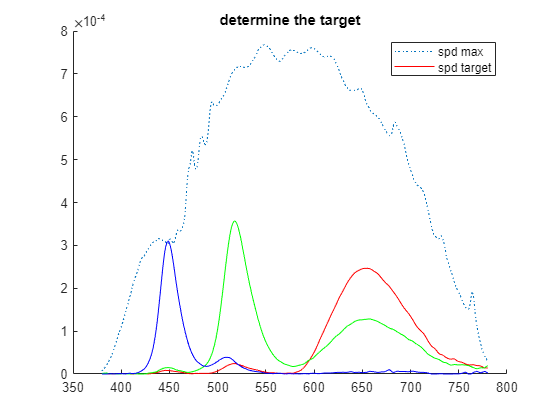

spec = spec_z24x(21:end,1:3);
determine_spd_targetx3(spec,ls.spd_max)

Determine RGB at the same time

function determine_spd_targetx3 (spd_target_orig,spd_max) 
sc = 0.07
spd_target = spd_target_orig .* sc;
clf
hold on
plot(380:780,spd_max,':')
plot(380:780,spd_target(:,1),'r')
plot(380:780,spd_target(:,2),'g')
plot(380:780,spd_target(:,3),'b')
legend('spd max','spd target')
title('determine the target')
end


function determine_spd_target (spd_target_orig,spd_max) 
sc = 0.08
spd_target = spd_target_orig .* sc;
clf
hold on
plot(380:780,spd_max)
plot(380:780,spd_target)
legend('spd max','spd target')
title('determine the target')
end